# Analysing Visual Coding Electrophysiology Data from the Allen Brain Observatory, with the Brain Observatory Toolbox

The Allen Brain Observatory resource [1] comprises datasets of neural activity obtained from the mouse visual cortex collected during visual stimulus presentation. The Visual Coding Neuropixels dataset [[2](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels)] consists of neural activity recordings obtained using multi-channel electrophysiology.

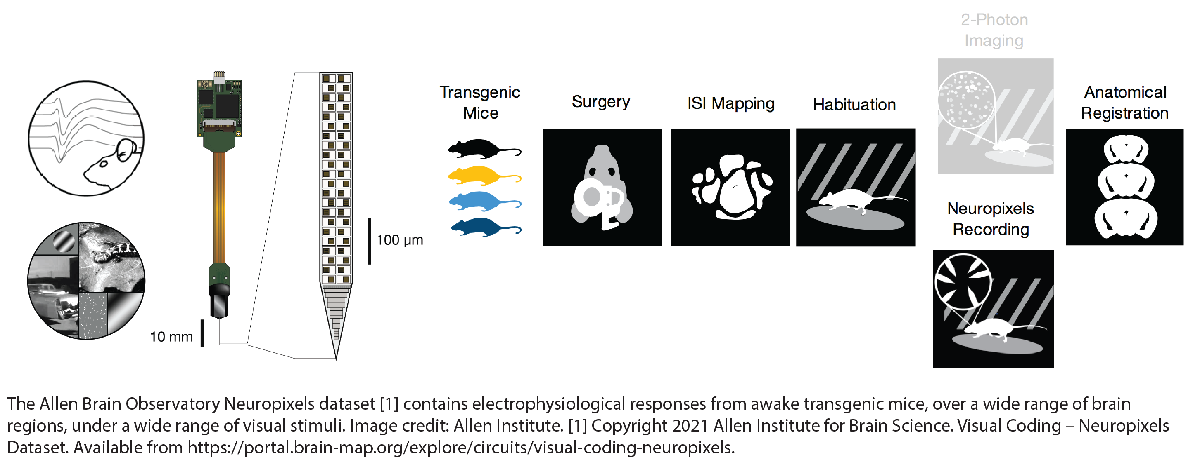

This example shows how to perform some simple analyses of visual responses by neurons in the mouse primary visual cortex using the [Brain Observatory Toolbox](https://github.com/emeyers/Brain-Observatory-Toolbox) (BOT). Neural response properties such as receptive field and orientation tuning are quantified, along with basic behavioural analysis.

The electrophysiology data for individual experimental sessions can be large — in the order of several GBytes for each experimental session. Be aware that running this demo will cause the download of approximately 5GB of data, which may take considerable time. This data will be cached by the toolbox, so that subsequent runs of the demo will be fast.

## Accessing data linked to a particular experimental session

Linked items and associated data to a particular experimental session can be queried after the session is selected and high-level information is obtained, as shown in the tutorial.

% Steps to obtain a single experimental session that meets arbitrary criteria,
% such as wild type animals with eye tracking data.

% Prepare for demo
clearvars;
warning('off');
clc;

% Obtain all sessions in the ephys dataset
sessions = bot.fetchSessions('ephys');

% Select sessions that include valid eye tracking data
sessions = sessions(~sessions.fail_eye_tracking, :);

% Select sessions on wild-type animals
sessions = sessions(sessions.full_genotype == "wt/wt", :)

sessions = 26×15 table
       id        unit_count    channel_count    probe_count         session_type          age_in_days    fail_eye_tracking    sex    full_genotype                                                      ephys_structure_acronyms                                                      isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _______________________    ___________    _________________    ___    _____________    ________________________________________


% Obtain a single experimental session
sess = bot.session(sessions(1, :));

### Accessing linked items: firing rates across brain regions

Linked items properties provide access to the probes, channels and units in this session.

For example, units can be accessed to compute their firing rates across the different brain regions stored in `.info.ephys_structure_acronyms`.

% get brain regions recorded
brainRegionsRecorded = sess.info.ephys_structure_acronyms;
brainRegionsRecorded = strip(split(brainRegionsRecorded,';'));

% filter units by brain regions
units = sess.units;
UnitsByBrainRegion = cellfun(@(x)(units(units.ephys_structure_acronym==x,:)),brainRegionsRecorded,...
'UniformOutput',0);

% get firing rates of all units by brain region
firingRatesByBrainRegion = cellfun(@(x)(x.firing_rate),UnitsByBrainRegion,'UniformOutput',0); 

Separating cortical (those beginning with VIS) from subcortical areas:

% separate cortical (VIS) and subcortical areas
corticalIndices = contains(brainRegionsRecorded,'VIS');
corticalFiringRates = cell2mat(firingRatesByBrainRegion(corticalIndices));
subCorticalFiringRates = cell2mat(firingRatesByBrainRegion(~corticalIndices));

...and plotting firing rates of cortical and sub-cortical regions along with some central statistics (medians):

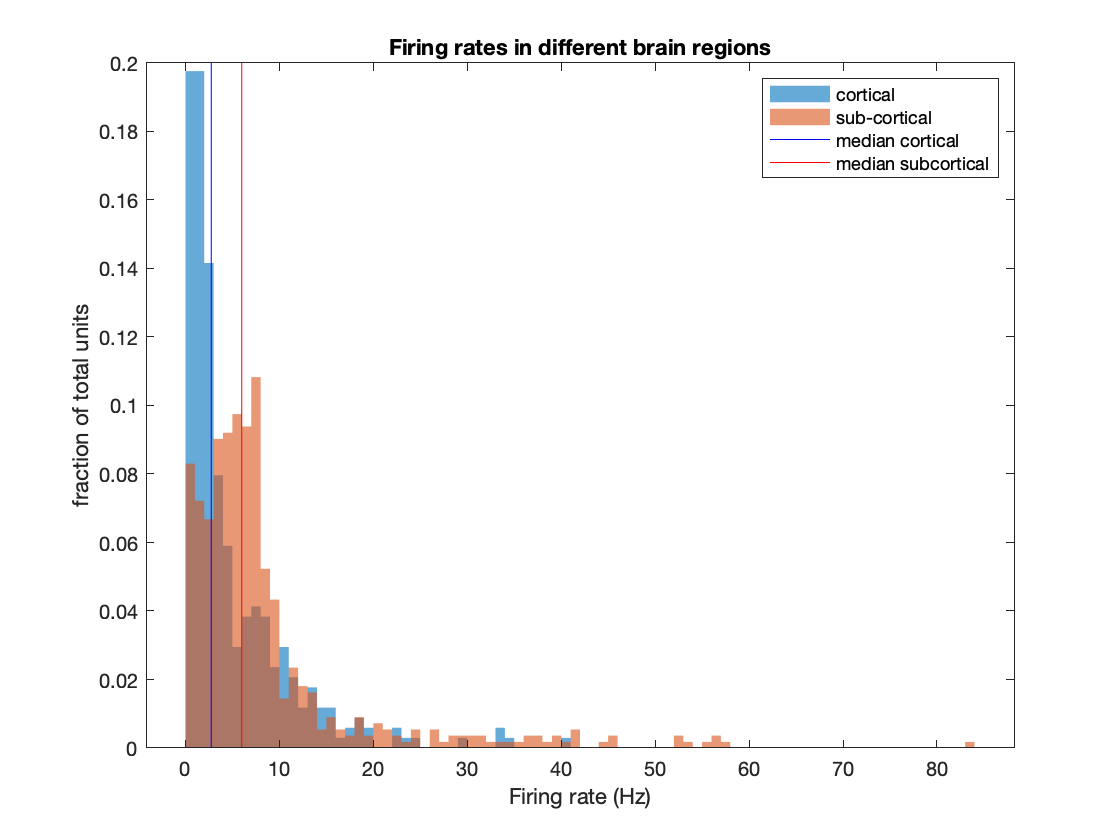

% plot histogram
histogram(corticalFiringRates,'Normalization','probability','BinWidth',1,'EdgeColor','none');hold on
histogram(subCorticalFiringRates,'Normalization','probability','BinWidth',1,'EdgeColor',"none"); hold off

% add statistics
line([median(corticalFiringRates) median(corticalFiringRates)],get(gca,'YLim'),'Color','b')
line([median(subCorticalFiringRates) median(subCorticalFiringRates)],get(gca,'YLim'),'Color','r')
legend({'cortical','sub-cortical','median cortical','median subcortical'})
title('Firing rates in different brain regions')
xlabel('Firing rate (Hz)')
ylabel('fraction of total units')

In this case, the visual cortex had lower firing rates than those observed from the sub-cortical regions (in this session, subcortical grey matter).

### Accessing linked file values: visualizing pupil location 

Actual data from the session can be retrieved using the linked file values. Due to large file sizes, this retrieval might be slow for the first run.

For example, `.pupil_data`  retrieves pupil tracking data to visualise the pupil location as a location density map.

% Get the table of pupil locations
pupil_loc = sess.pupil_data

pupil_loc = 288131×16 table
    timestamps    corneal_reflection_center_x    corneal_reflection_center_y    corneal_reflection_height    corneal_reflection_width    corneal_reflection_phi    pupil_center_x    pupil_center_y    pupil_height    pupil_width    pupil_phi    eye_center_x    eye_center_y    eye_height    eye_width    eye_phi 
    __________    ___________________________    ___________________________    _________________________    ________________________    ______________________    ______________    ______________    ____________    ___________</

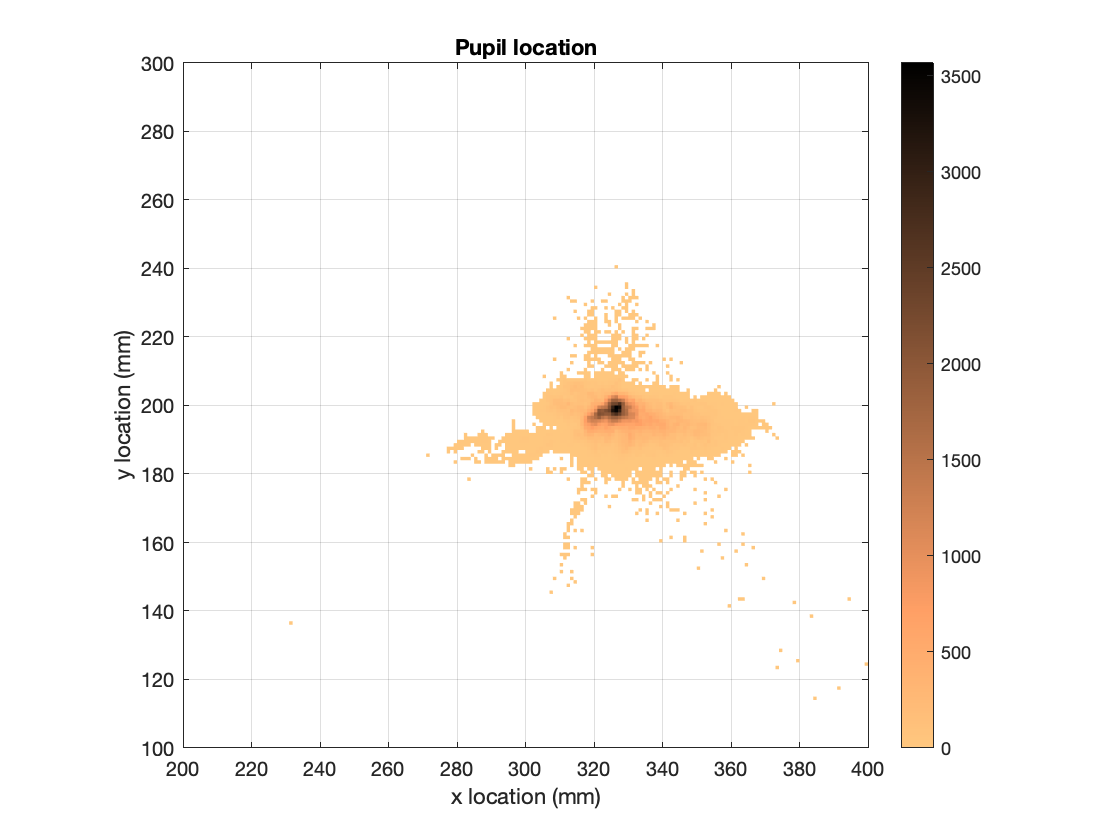

% Plot a 2D histogram of pupil location
histogram2(pupil_loc.pupil_center_x, pupil_loc.pupil_center_y, 'DisplayStyle', 'tile');
xlim([200 400]);
ylim([100 300]);
cmap = copper();
colormap(cmap(end:-1:1, :));
axis square;
xlabel('x location (mm)');
ylabel('y location (mm)');
title('Pupil location');
colorbar

### Examining details of an individual stimulus presentation (Gabor patches)

Sessions also contain information about stimuli presentations. One of the stimuli used in this session were Gabor patches of different orientations that were distributed across the visual field in a grid-like manner.

% Get a full table of individual stimulus presentations
stimuli = sess.stimulus_presentations;

% extract Gabor patches from stimulus set
StimIndices = stimuli(stimuli.stimulus_name=='gabors', :);

% extract stimulus locations and orientations
StimXloc = unique(StimIndices.x_position);
StimYloc = unique(StimIndices.y_position);
StimOrnt = unique(StimIndices.orientation);

% display stimulus properties
['stimulus x pos: ',num2str(StimXloc'),newline,...
    'stimulus y pos: ',num2str(StimYloc'),newline,...
    'stimulus orientation: ',num2str(StimOrnt')]

ans =     'stimulus x pos: -40 -30 -20 -10   0  10  20  30  40
     stimulus y pos: -40 -30 -20 -10   0  10  20  30  40
     stimulus orientation: 0  45  90'


## Accessing probe-centric data

As mentioned in the tutorial, methods from the `probe` object can be used to access data associated with the probe, such as current-source density (CSD) measurements. We extract the CSD data for the first probe in the session.

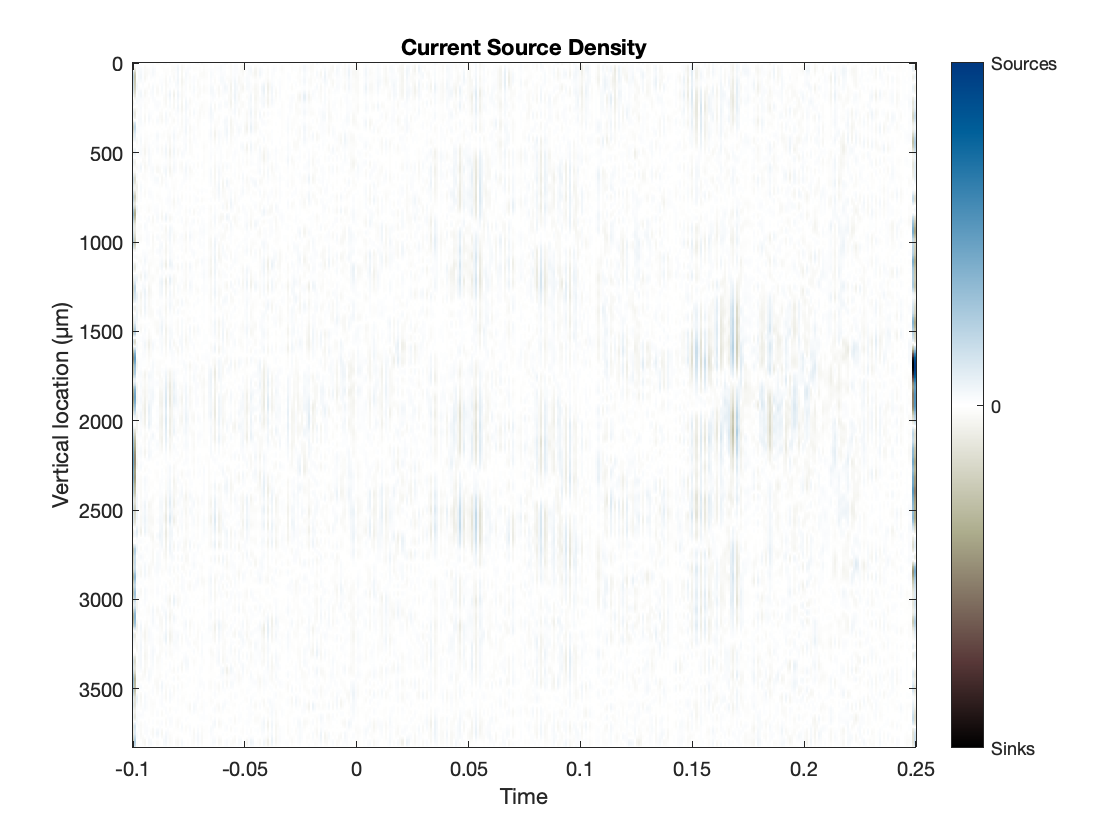

% Get the probe object
probes = sess.probes;
probe = bot.probe(probes(1, :));

% Extract CSD data for this probe
tt = probe.csdData.data; % timetable 
vposns = probe.csdData.verticalPositions;

% Plot the CSD data
figure, imagesc(seconds(tt.Time), vposns, table2array(tt));
colormap(vertcat(flipud(1-bone()), 1-copper()));
max_amp = max(abs(caxis));
colorbar('Ticks',[-max_amp,0,max_amp],'Ticklabels',{'Sinks','0','Sources'})
caxis([-1 1] * max_amp);
xlabel('Time');
ylabel('Vertical location (µm)');
title('Current Source Density');

## Accessing data from a single unit

All units in the current session can be retrieved using `.units` and then filtered according to some criteria, as shown in the tutorial. Then, an individual unit object can be constructed.

units = sess.units;
% Filter the units from the primary visual cortex ('VISp')
units = units(units.ephys_structure_acronym == 'VISp', :);
% Obtain a `unit` object for the first unit
unit = bot.unit(units(1, :));

### Examining stimulus-related responses for this unit

After constructing a unit object, the stimulus-related responses for the particular unit can now be queried.

#### Determining the receptive field for this unit

First, the responses of this unit to the different Gabor patches are displayed to determine its receptive field.

The stimulus IDs for the Gabor patches will be used to extract spike counts for each spatial presentation of the Gabor patch using the `getConditionwiseSpikeStatistics()` method. Since all stimulus conditions were not repeated in all experiments, some of these are invalid for the current unit and will be populated by `NaN` values which are removed.

% extract spk statistics by stimulus conditions and remove invalid conditions
spkCounts = sess.getConditionwiseSpikeStatistics(StimIndices.stimulus_presentation_id,unit.id);
spkCounts = rmmissing(spkCounts);

Loop through the Gabor patches to plot the spike counts for each stimulus location:

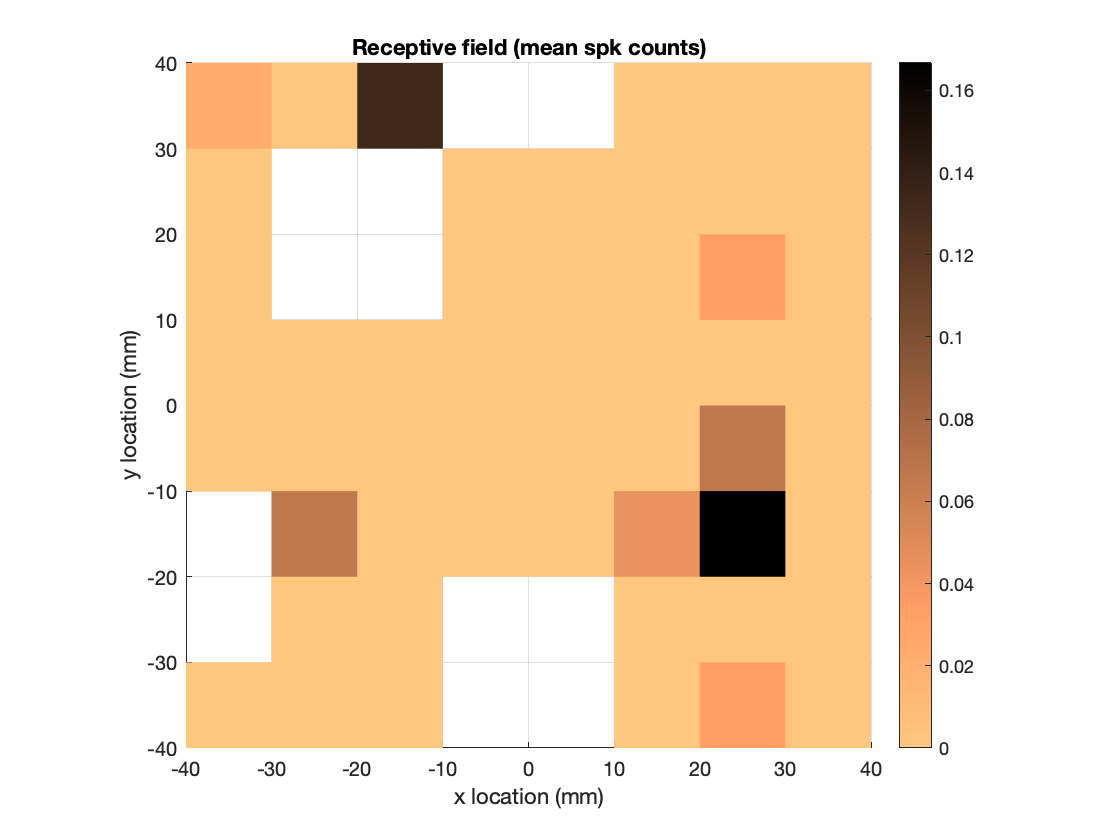

scnt = zeros(length(StimXloc),length(StimYloc));
for ii = 1:length(StimXloc) % loop through stimulus positions
    for jj = 1:length(StimYloc)
        validStimIndices = StimIndices.x_position == StimXloc(ii) & ...
            StimIndices.y_position == StimYloc(jj);
        StimConditionIds = unique(StimIndices.stimulus_condition_id(validStimIndices)); % matching stim conditions
        ValidConditionIds = ismember(spkCounts.stimulus_condition_id,StimConditionIds); % find stim conditions valid for unit
        scnt(ii,jj) = sum(spkCounts.spike_count(ValidConditionIds))/...
            sum(spkCounts.stimulus_presentation_count(ValidConditionIds));
    end
end

% plot the data
surf(StimXloc,StimYloc,scnt)
shading flat
axis square
view([0 90])
cmap = copper();
colormap(cmap(end:-1:1, :));
colorbar
ylabel('y location (mm)')
xlabel('x location (mm)')
title('Receptive field (mean spk counts)')

#### Determining orientation tuning for this unit

Next, an orientation tuning curve for this unit will be computed using the `"static_gratings"` [stimuli](http://observatory.brain-map.org/visualcoding/stimulus/static_gratings#:~:text=The%20static%20grating%20stimulus%20consists,the%20position%20of%20the%20grating).&text=At%20the%20intersections%20of%20these,corresponding%20to%20a%20different%20phase.). 

% Identify static grating stimuli
stimuli = sess.stimulus_presentations;
staticGratingIndices = stimuli(stimuli.stimulus_name == "static_gratings", :);
stimulusPresentationIds = staticGratingIndices.stimulus_presentation_id;

To choose a selective time window for the response, a peri-stimulus time histogram (PSTH) of several unit responses from the same probe will first be created, and the unit responses are measured by the `getPresentationwiseSpikeCounts()` method.

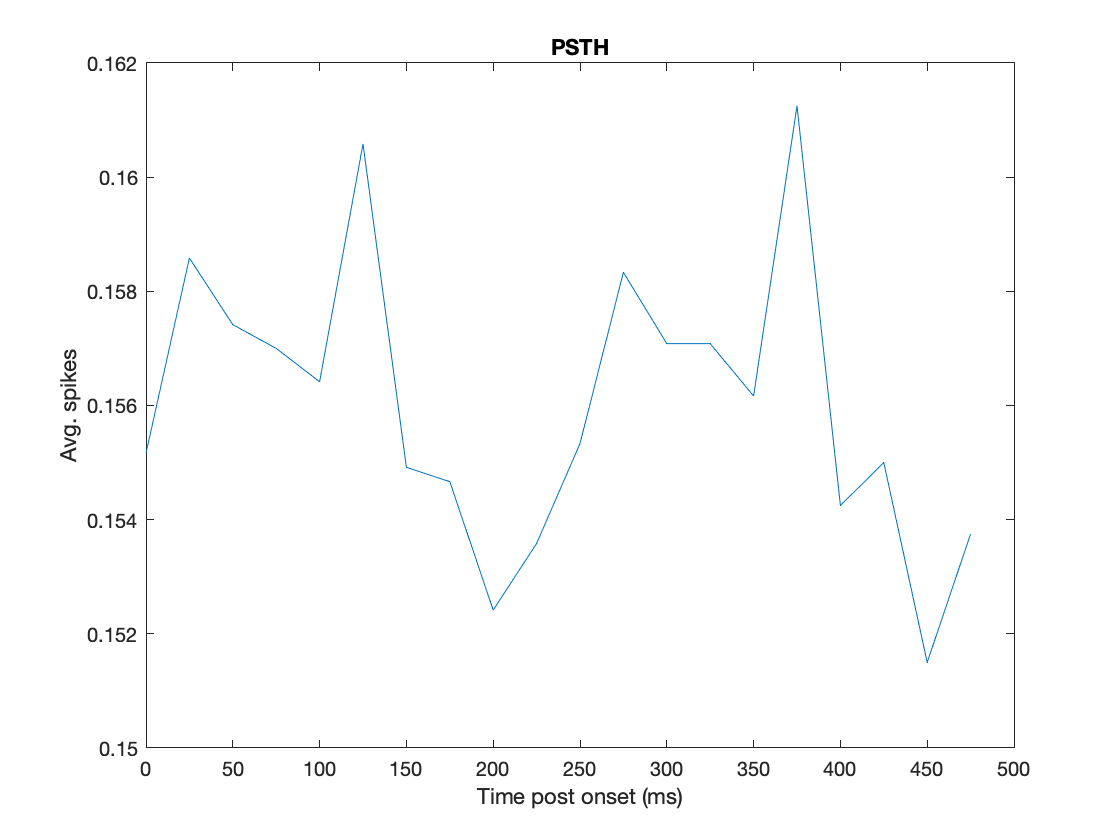

% Build a PSTH (enter the number of trials to use for PSTH calculation,
% more trials will require longer computational time)
nPsthUnits = str2double("2"); % please enter a number between 2 and 20
timeBins = 0:25e-3:500e-3;
psth = sess.getPresentationwiseSpikeCounts(timeBins, stimulusPresentationIds, unit.probe.units{1:nPsthUnits, 'id'});
% Plot the PSTH
plot(timeBins(1:end-1) * 1e3, mean(psth, [2 3]));
xlabel('Time post onset (ms)');
ylabel('Avg. spikes');
title('PSTH');

Then, the particular unit can be tuned to the orientation of a visual stimulus. 

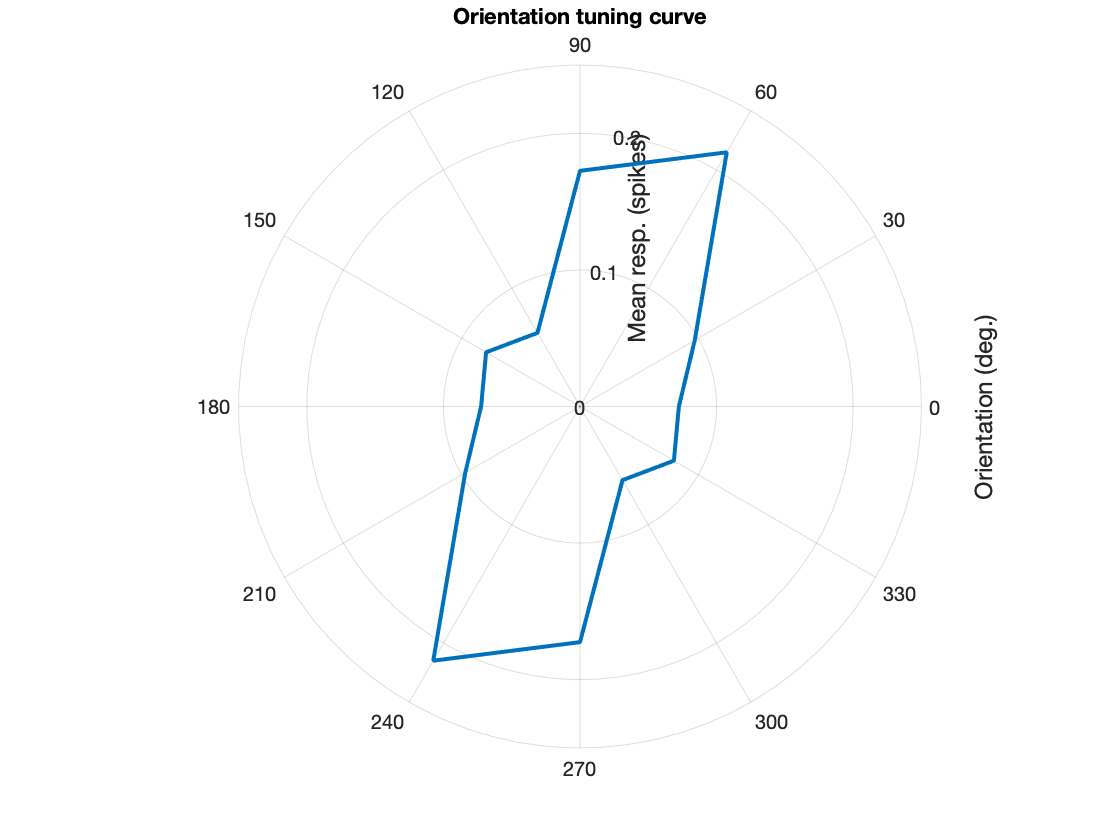

% Compute stimulus responses after selecting response window
respWindow = [250 500] * 1e-3;
responses = sess.getPresentationwiseSpikeCounts(respWindow, stimulusPresentationIds, unit.id);
% Collect stimuli by stimulus orientation
stimOrientation = staticGratingIndices.orientation;
[condOrientation, ~, oriIndex] = unique(stimOrientation);
blanks = isnan(stimOrientation);
oriIndex(blanks) = 7;
% Calculate mean and std. dev. of responses per stimulus orientation
respMean = accumarray(oriIndex, responses, [], @mean);
respStd = accumarray(oriIndex, double(responses), [], @std);
% Plot an orientation tuning curve
orientation = deg2rad(condOrientation);
orientation = [orientation(1:6); orientation(1:6) + pi; orientation(1)];
polarplot(orientation, respMean([1:6 1:6 1]), 'LineWidth', 2);
a = gca;
a.RAxis.Label.String = 'Mean resp. (spikes)';
a.ThetaAxis.Label.String = 'Orientation (deg.)';
title('Orientation tuning curve')

## References

[1] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[2] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).